## Analysis:

clear all;
eeglab;

         You may experience errors if a plugin overloads a MATLAB function
Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\anhtn\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.8.3 to the path - new version 3.8.4 available
--------------------------------------------------------------------------------------------------------------------------------------------
%Equivalent command:
 erplab_running_version(   'tooltype', 'ERPLAB' 'version', '10.02' );
--------------------------------------------------------------------------------------------------------------------------------------------
Go back to ERPLAB menu

EEGLAB: adding "ERPLAB" v10.02 (see >> help eegplugin_erplab) - new version 12.00 available
EEGLAB: adding "Fieldtri

close all

setup_AOE

AO_alpha_band = 7.5:0.5:13.5;
AO_beta_band = 17:0.5:24;
AO_bands = {AO_alpha_band, AO_beta_band};

AE_alpha_band = 9:0.5:13;
AE_beta_band = 19:0.5:24;
AE_bands = {AE_alpha_band, AE_beta_band};

AO_onset_times = 1000;
AE_onset_times = 0;

exp = 1;
AO_times = times_exp_cell{exp};
exp = 2;
AE_times = times_exp_cell{exp};




## Compute mean and std ERD values over time for each frequency band, each condition, each channel, during AO and AE

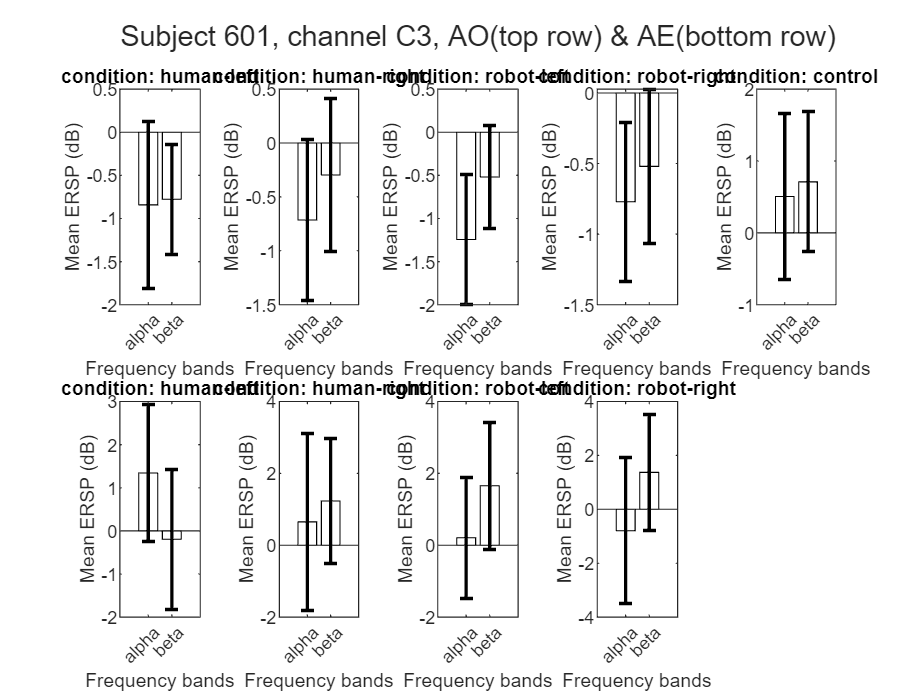

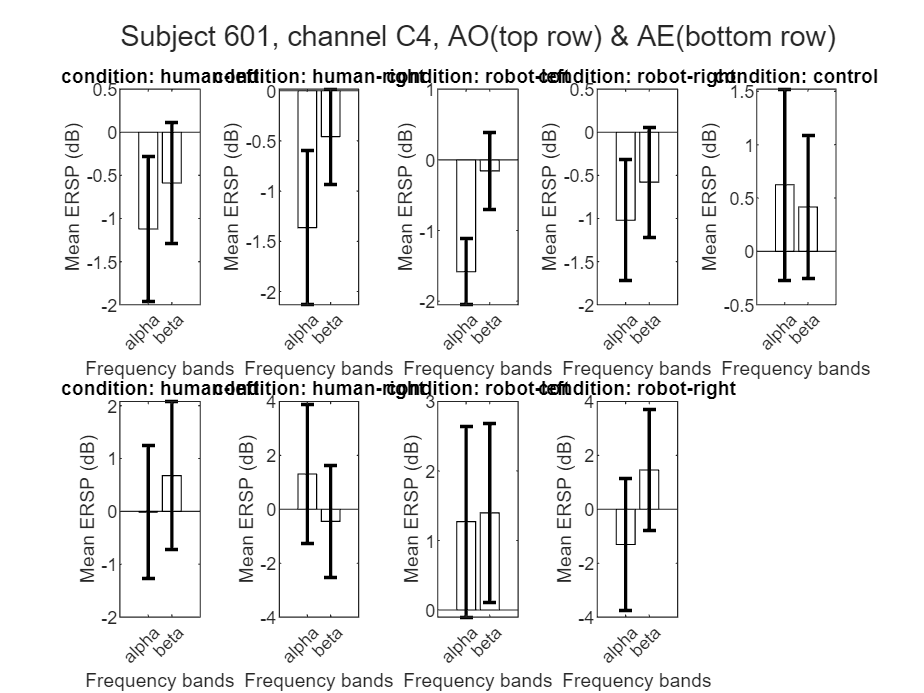

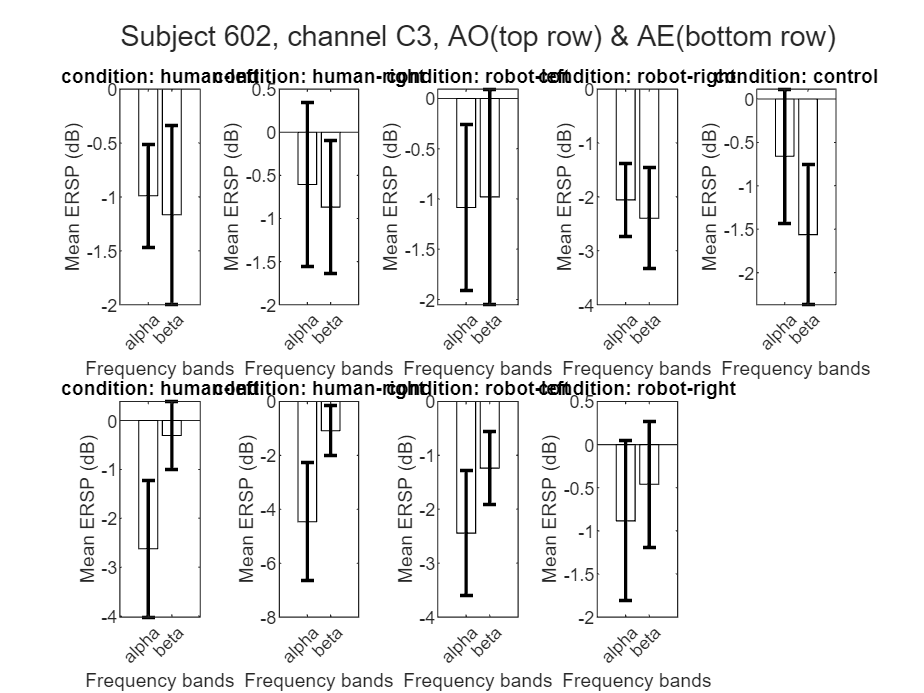

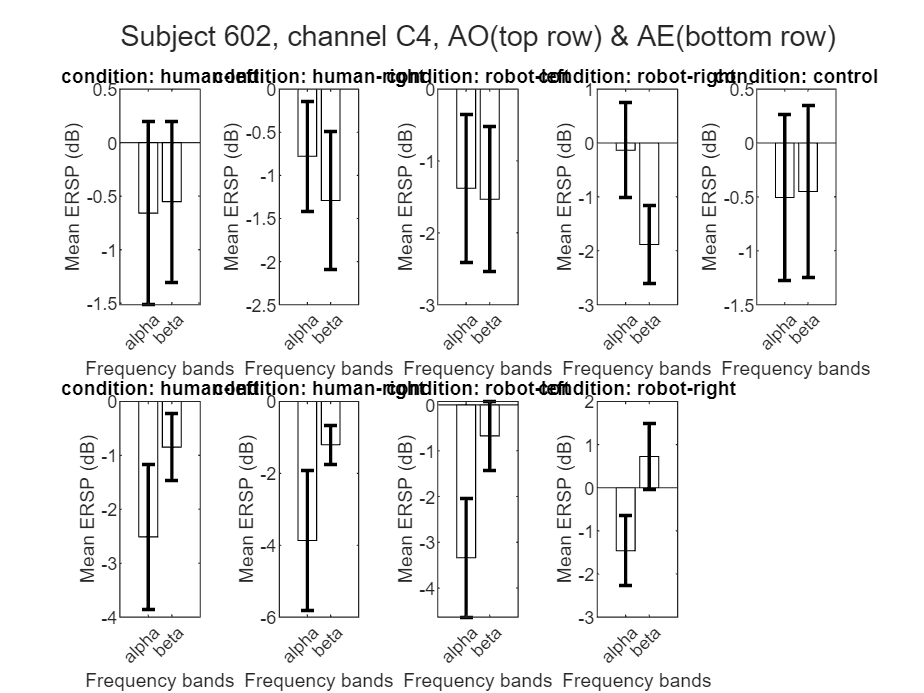

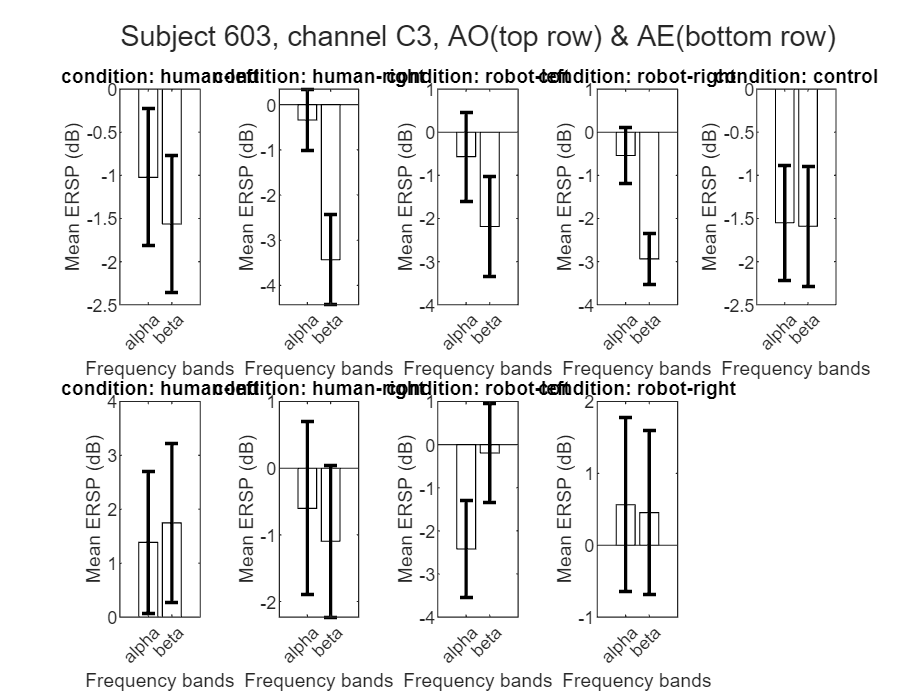

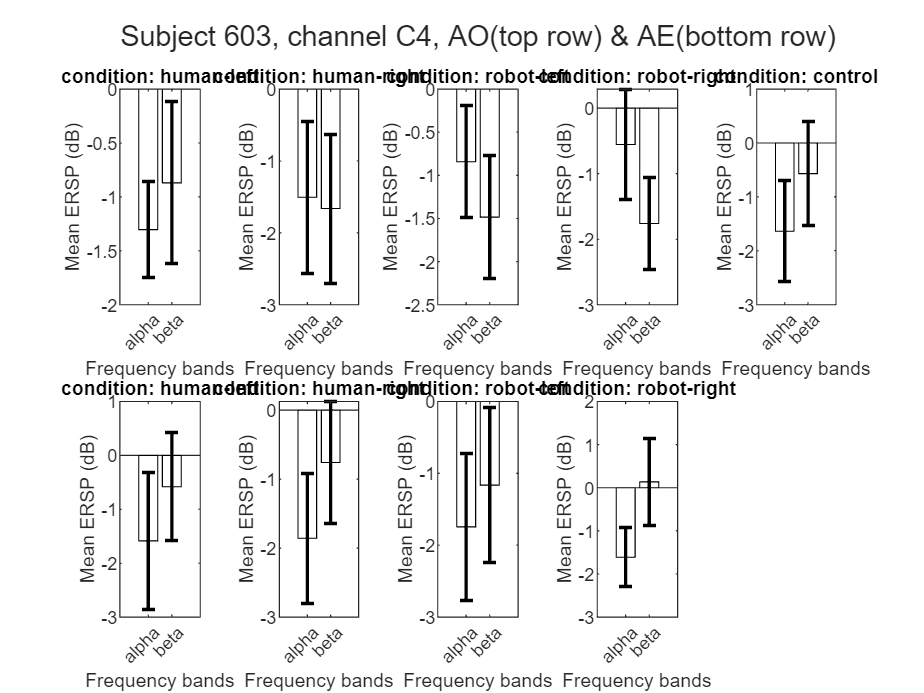

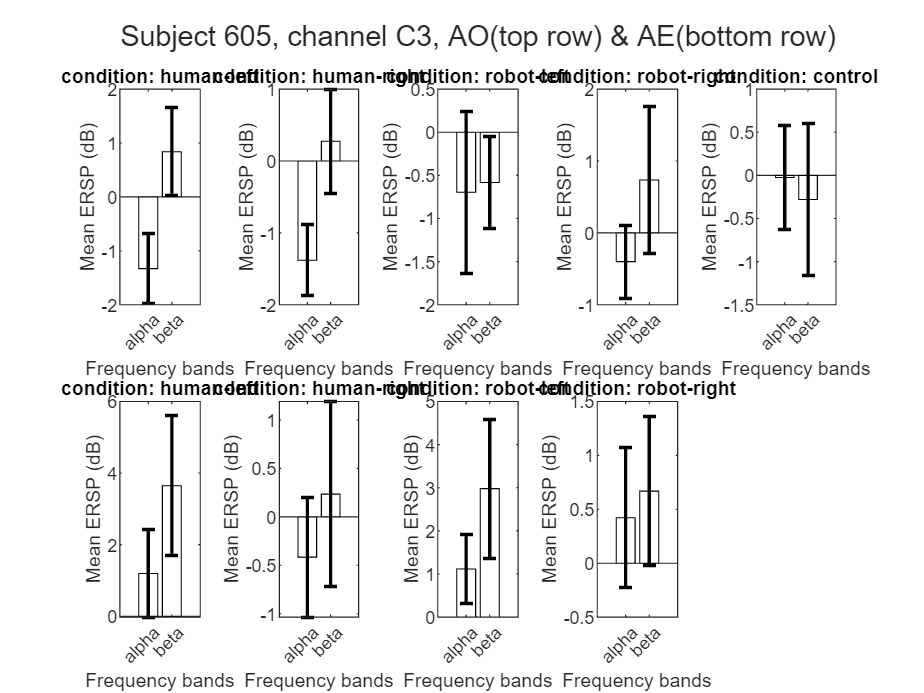

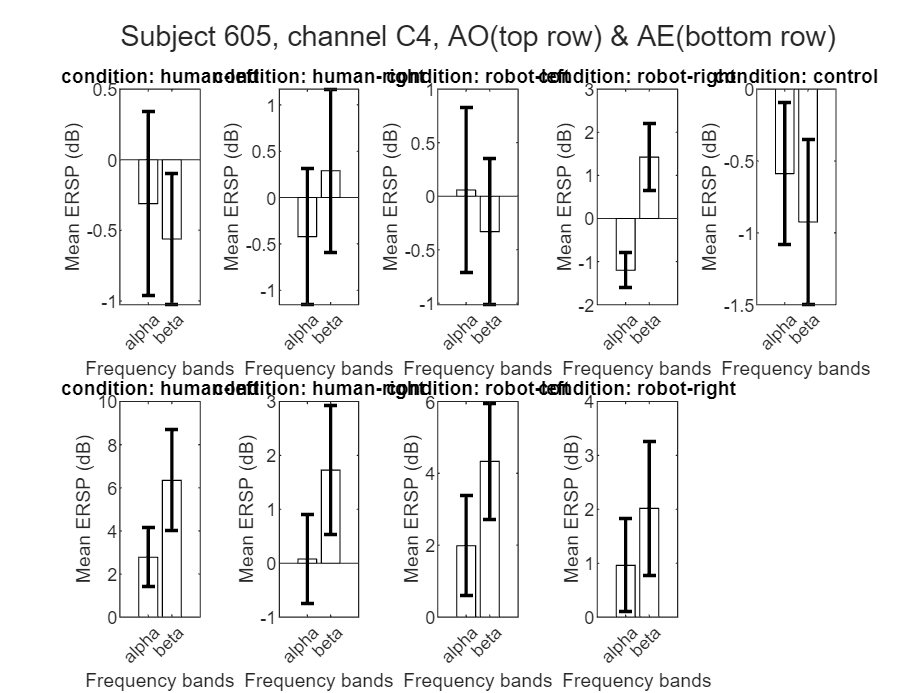

for trial_idx = 1:length(trials)
    ersp_exp_all = ALL_ERSP_trial{trial_idx};
    
    for chan = 1:length(chan_names)
        exp = 1;
        AO_times = times_exp_cell{exp};
        figure; t0 = tiledlayout(2,5);
        title(t0, ['Subject ' subject_idx{trial_idx} ', channel ' chan_names{chan} ', AO(top row) & AE(bottom row)'])
        for cond = 1:length(AO_markerVal_cell)
            ersp = ersp_exp_all{chan, exp}{cond};
            
            AO_onset_idx = find(AO_times >= AO_onset_times);
            
            nexttile(t0);
            
            AO_ersp_mean_band = zeros(length(AO_bands), length(AO_onset_idx));
            for band = 1:length(AO_bands)
                AO_ersp_mean_band(band, :) = mean(ersp(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_onset_idx) );
                
            end
            
            mean_ersp = mean(AO_ersp_mean_band, 2);
            std_ersp = std(AO_ersp_mean_band, 0, 2);
            
            % plot
            bar(mean_ersp, 'w');
            hold on
            errorbar(1:numel(mean_ersp), mean_ersp', std_ersp', 'k', 'LineWidth', 1.5, 'linestyle', 'none');
            hold off
            
            xticks(1:numel(mean_ersp)); % Set the tick locations
            xticklabels(band_names); % Set the tick labels
            xlabel('Frequency bands');
            ylabel('Mean ERSP (dB)');
            title(['condition: ' markerLabel{cond}]);
            
        end
        
        exp = 2;
        AE_times = times_exp_cell{exp};
        % figure; t2 = tiledlayout(2,2);
        % title(t2, ['Subject ' trials{trial_idx} ', channel ' chan_names{chan} ', AE'])
        
        for cond = 1:length(AE_markerVal_cell)
            ersp = ersp_exp_all{chan, exp}{cond};
            
            AE_onset_idx = find(AE_times >= AE_onset_times);
            
            nexttile(t0);
            
            AE_ersp_mean_band = zeros(length(AE_bands), length(AE_onset_idx));
            for band = 1:length(AE_bands)
                AE_ersp_mean_band(band, :) = mean(ersp(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_onset_idx) );
                
            end
            
            mean_ersp = mean(AE_ersp_mean_band, 2);
            std_ersp = std(AE_ersp_mean_band, 0, 2);
            
            % plot
            bar(mean_ersp, 'w');
            hold on
            errorbar(1:numel(mean_ersp), mean_ersp', std_ersp', 'k', 'LineWidth', 1.5, 'linestyle', 'none');
            hold off
            
            xticks(1:numel(mean_ersp)); % Set the tick locations
            xticklabels(band_names); % Set the tick labels
            xlabel('Frequency bands');
            ylabel('Mean ERSP (dB)');
            title(['condition: ' markerLabel{cond}]);
            
        end
        
    end
end

Note: Some figures show very high variability, implying the fluctuation in power over time. Further analysis should check this temporal dynamics

## try collapsing data from C3 and C4

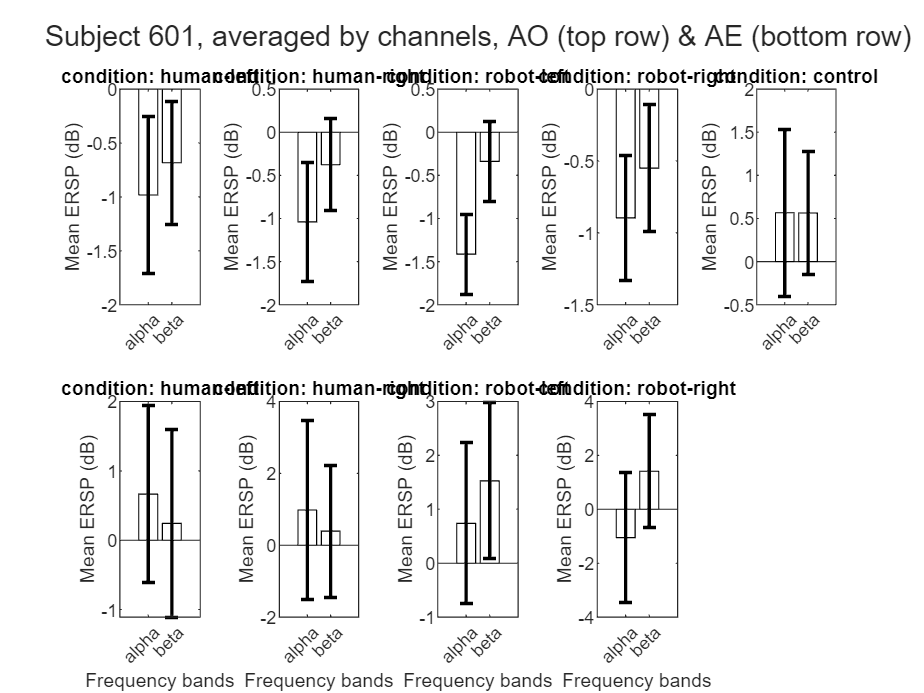

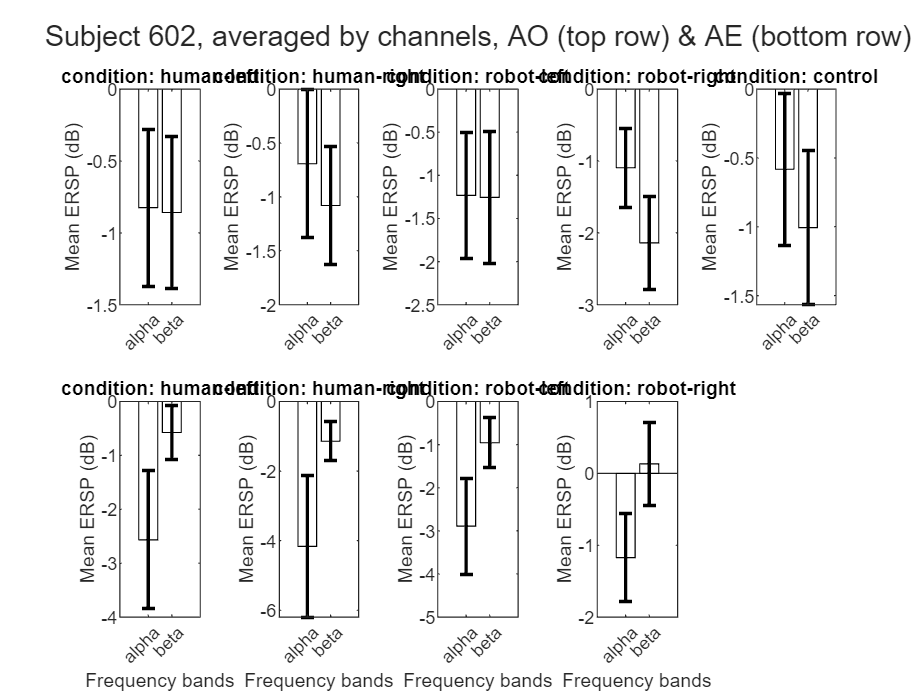

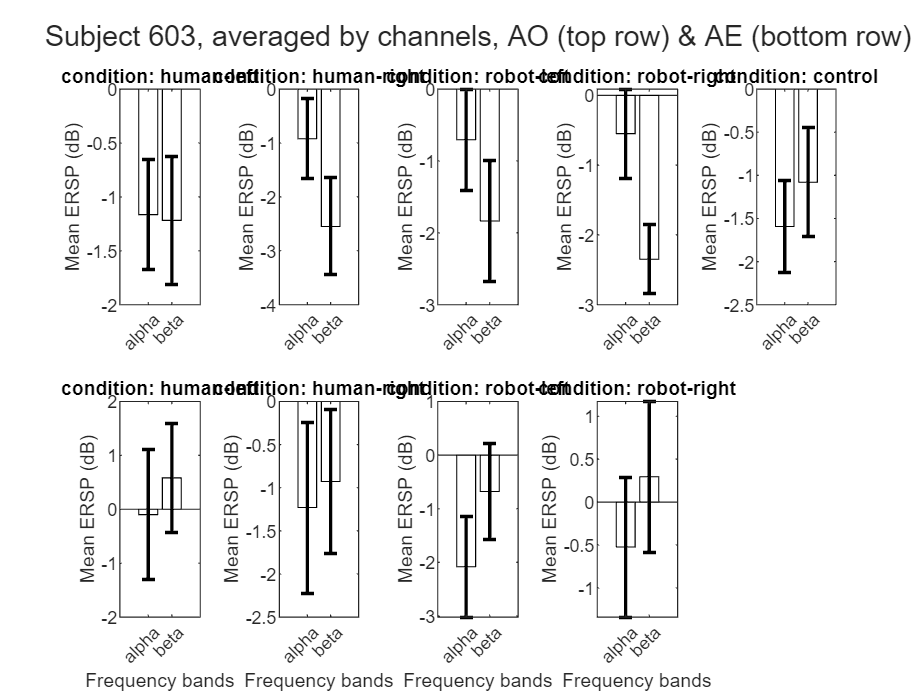

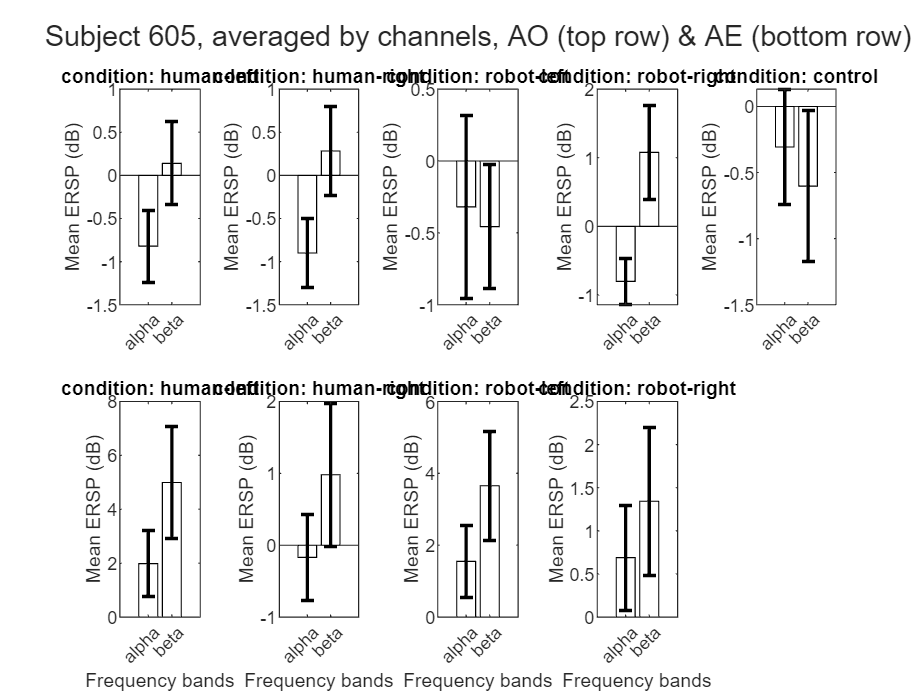

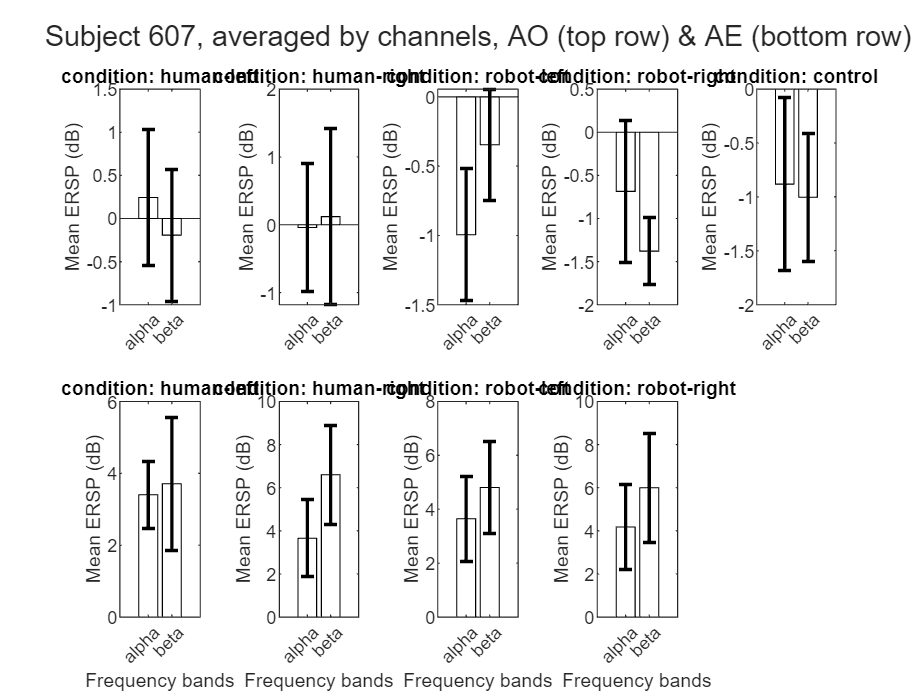

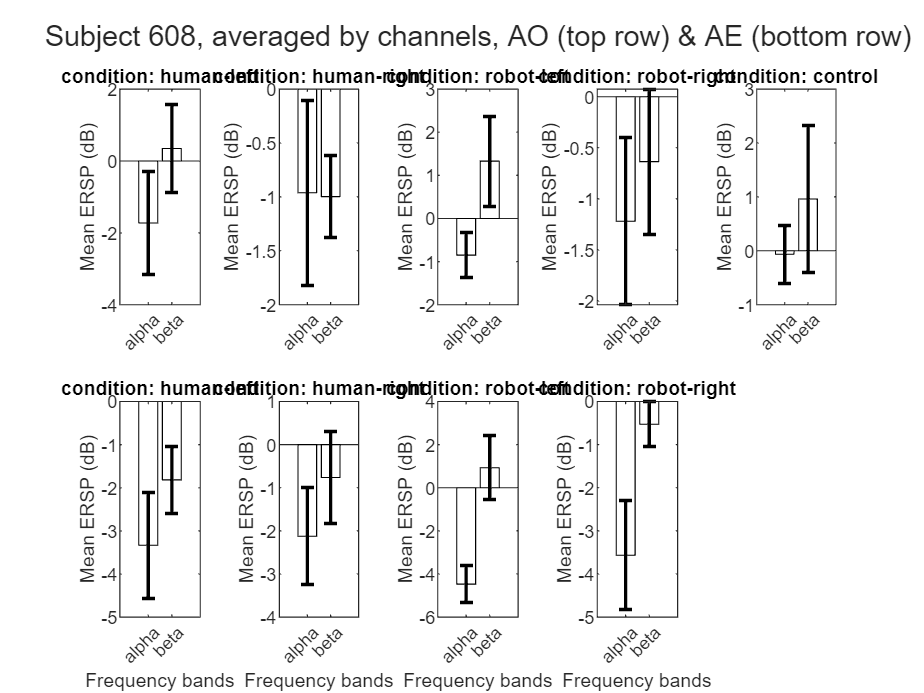

% ersp_all_mean_chan: a 3x2 cell (3 subjects, 2 experiments)
% each cell element is a 2xn cell (2 freq bands, n = # of conditions)
% each smaller element is a ERSP data (averaged across 2 channels)

ersp_all_mean_chan = cell(length(trials), length(experiments));
for trial_idx = 1:length(trials)
    ersp_exp_all = ALL_ERSP_trial{trial_idx};
    
    exp = 1;
    ersp_cond_cell = cell(length(AO_bands),length(AO_markerVal_cell));
    for cond = 1:length(AO_markerVal_cell)
        for band = 1:length(AO_bands)
            ersp_C3 = ersp_exp_all{1, exp}{cond};
            ersp_C3 = ersp_C3(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), :);
            
            ersp_C4 = ersp_exp_all{2, exp}{cond};
            ersp_C4 = ersp_C4(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), :);
            
            ersp_mean_chan = (ersp_C3 + ersp_C4)/2;
            
            ersp_cond_cell{band, cond} = ersp_mean_chan;
            
        end
    end
    ersp_all_mean_chan{trial_idx, exp} = ersp_cond_cell;
    
    exp = 2;
    ersp_cond_cell = cell(length(AE_bands),length(AE_markerVal_cell));
    for cond = 1:length(AE_markerVal_cell)
        for band = 1:length(AE_bands)
            ersp_C3 = ersp_exp_all{1, exp}{cond};
            ersp_C3 = ersp_C3(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), :);
            
            ersp_C4 = ersp_exp_all{2, exp}{cond};
            ersp_C4 = ersp_C4(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), :);
            
            ersp_mean_chan = (ersp_C3 + ersp_C4)/2;
            
            ersp_cond_cell{band, cond} = ersp_mean_chan;
        end
    end
    ersp_all_mean_chan{trial_idx, exp} = ersp_cond_cell;
    
end

% compute mean and std through all times for each subject, experiment, condition
for trial_idx = 1:length(trials)
    exp = 1;
    ersp_cond_cell = ersp_all_mean_chan{trial_idx, exp};
    
    AO_times = times_exp_cell{exp};
    AO_onset_idx = find(AO_times >= AO_onset_times);
    
    figure; t0 = tiledlayout(2,5);
    title(t0, ['Subject ' subject_idx{trial_idx} ', averaged by channels, AO (top row) & AE (bottom row)'])
    
    for cond = 1:length(AO_markerVal_cell)
        nexttile(t0);
        AO_ersp_mean_band = zeros(length(AO_bands), length(AO_onset_idx));
        for band = 1:length(AO_bands)
            ersp = ersp_cond_cell{band, cond};
            AO_ersp_mean_band(band, :) = mean(ersp(:, AO_onset_idx) );
        end
        
        mean_ersp = mean(AO_ersp_mean_band, 2);
        std_ersp = std(AO_ersp_mean_band, 0, 2);
        
        % plot
        bar(mean_ersp, 'w');
        hold on
        errorbar(1:numel(mean_ersp), mean_ersp', std_ersp', 'k', 'LineWidth', 1.5, 'linestyle', 'none');
        hold off
        xticks(1:numel(mean_ersp)); % Set the tick locations
        xticklabels(band_names); % Set the tick labels
        % xlabel('Frequency bands');
        ylabel('Mean ERSP (dB)');
        title(['condition: ' markerLabel{cond}]);
    end
    
    % AE
    exp = 2;
    ersp_cond_cell = ersp_all_mean_chan{trial_idx, exp};
    
    AE_times = times_exp_cell{exp};
    AE_onset_idx = find(AE_times >= AE_onset_times);
    
    for cond = 1:length(AE_markerVal_cell)
        nexttile(t0);
        AE_ersp_mean_band = zeros(length(AE_bands), length(AE_onset_idx));
        for band = 1:length(AE_bands)
            ersp = ersp_cond_cell{band, cond};
            AE_ersp_mean_band(band, :) = mean(ersp(:, AE_onset_idx) );
        end
        
        mean_ersp = mean(AE_ersp_mean_band, 2);
        std_ersp = std(AE_ersp_mean_band, 0, 2);
        
        % plot
        bar(mean_ersp, 'w');
        hold on
        errorbar(1:numel(mean_ersp), mean_ersp', std_ersp', 'k', 'LineWidth', 1.5, 'linestyle', 'none');
        hold off
        xticks(1:numel(mean_ersp)); % Set the tick locations
        xticklabels(band_names); % Set the tick labels
        xlabel('Frequency bands');
        ylabel('Mean ERSP (dB)');
        title(['condition: ' markerLabel{cond}]);
    end
end

Note: Collapsing C3 and C4 might not be a good idea due to the variability in ERSP between these channels' data

## Compute and plot mean and std for each 250 ms time window, including the baseline

Segment ERSP of each condition, each freq band, each experiment, each channel, each subject Each plot should shows time dynamics of diff conditions, using errorbar

% AO_onset_times = 1000;
% AE_onset_times = 0;
% window_size = 250;
% 
% % find the indices of time points lying within consecutive time windows of 250 seconds  
% AO_window_idx = extract_window_indices_wbl(AO_times, AO_onset_times, window_size, AO_baseline*1000);
% AE_window_idx = extract_window_indices_wbl(AE_times, AE_onset_times, window_size, AE_baseline*1000);
% 
% x_shift= [-0.2 -0.1 0 0.1 0.2];
% 
% for trial_idx = 1:length(trials)
%     ersp_exp_all = ALL_ERSP_trial{trial_idx};
%     for chan = 1:length(chan_names)
% 
%         figure; t0 = tiledlayout(2,2);
%         title(t0, ['Subject ' trials{trial_idx} ', channel ' chan_names{chan} ', AO(top row) & AE(bottom row)'])
% 
%         exp = 1;
%         for band = 1:length(band_names)
% 
%             nexttile(t0); hold on
%             for cond = 1:length(AO_markerVal_cell)
%                 ersp = ersp_exp_all{chan, exp}{cond};
% 
%                 mean_ersp_tw = zeros(1, length(AO_window_idx));
%                 std_ersp_tw = zeros(1, length(AO_window_idx));
%                 for tw = 1:length(AO_window_idx)
%                     ersp_tw = mean(ersp(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_window_idx{tw}) );
%                     mean_ersp_tw(tw) = mean(ersp_tw);
%                     std_ersp_tw(tw) = std(ersp_tw);
%                 end
%                 x = 0:numel(AO_window_idx)-1;
%                 errorbar(x+x_shift(cond), mean_ersp_tw, std_ersp_tw, "Marker", markerSymbol(cond), ...
%                     'Color',markerColor(cond), "LineStyle", markerCurveStyle(cond),"MarkerSize", markerSize);
% 
%             end
%             xticks(x);
%             xlim([x(1)-1 x(end)+1]);
%             xlabel('Time windows (250 ms)');
%             ylabel('Mean ERSP (dB)'); yline(0, 'k--', 'Alpha', 0.5)
%             title([band_names{band} ' band']);
%             hold off
%         end
%         legend(markerLabel, 'Location','eastoutside')
% 
% 
%         exp = 2;
%         for band = 1:length(band_names)
% 
%             nexttile(t0); hold on
%             for cond = 1:length(AE_markerVal_cell)
%                 ersp = ersp_exp_all{chan, exp}{cond};
% 
%                 mean_ersp_tw = zeros(1, length(AE_window_idx));
%                 std_ersp_tw = zeros(1, length(AE_window_idx));
%                 for tw = 1:length(AE_window_idx)
%                     ersp_tw = mean(ersp(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_window_idx{tw}) );
%                     mean_ersp_tw(tw) = mean(ersp_tw);
%                     std_ersp_tw(tw) = std(ersp_tw);
%                 end
% 
%                 x = 0:numel(AE_window_idx)-1;
%                 errorbar(x+x_shift(cond), mean_ersp_tw, std_ersp_tw, "Marker", markerSymbol(cond),"MarkerSize", markerSize, ...
%                     'Color',markerColor(cond), "LineStyle", markerCurveStyle(cond));
% 
%             end
%             xticks(x);
%             xlim([x(1)-1 x(end)+1]);
%             xlabel('Time windows (250 ms)');
%             ylabel('Mean ERSP (dB)');
%             title([band_names{band} ' band']);
%             yline(0, 'k--', 'Alpha', 0.5);
%             hold off
%         end
%         legend(markerLabel(1:end-1), 'Location','eastoutside')
% 
%     end
% end


It's hard to interpret this results.

S0 AO: ERD present in not only during AO but also with control

S0 AE: a consistent pattern: ERD peak at 2nd time window

## Plot temporal dynamics, but averaged across all subjects

Average ersp across all subjects, all channels

Plot temporal dynamics like above section

for each experiment, each condition and each freq band

% 
% AO_onset_times = 1000;
% AE_onset_times = 0;
% window_size = 250;
% % find the indices of time points lying within consecutive time windows of 250 seconds  
% AO_window_idx = extract_window_indices_wbl(AO_times, AO_onset_times, window_size, AO_baseline*1000);
% AE_window_idx = extract_window_indices_wbl(AE_times, AE_onset_times, window_size, AE_baseline*1000);
% 
% x_shift= [-0.2 -0.1 0 0.1 0.2];
% 
% figure; t0 = tiledlayout(2,2);
% title(t0, 'Average across all subjects & channels')
% 
% exp = 1;
% for band = 1:length(band_names)
% 
%     nexttile(t0); hold on
%     for cond = 1:length(AO_markerVal_cell)
% 
%         count = 0;
%         ersp_average_subj = zeros(size(ALL_ERSP_trial{1}{1, exp}{1}));
%         for chan = 1:length(chan_names)
% 
%             for trial_idx = 1:length(trials)
%                 ersp_cond_cell = ALL_ERSP_trial{trial_idx}{chan, exp}{cond};
%                 ersp_average_subj = ersp_average_subj + ersp_cond_cell;
%                 count = count +1;
% 
%             end
%         end
% 
%         ersp_average_subj = ersp_average_subj / count;
% 
%         mean_ersp_tw = zeros(1, length(AO_window_idx));
%         std_ersp_tw = zeros(1, length(AO_window_idx));
%         for tw = 1:length(AO_window_idx)
%             ersp_tw = mean(ersp_average_subj(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_window_idx{tw}) );
%             mean_ersp_tw(tw) = mean(ersp_tw);
%             std_ersp_tw(tw) = std(ersp_tw);
%         end
%         x = 0:numel(AO_window_idx)-1;
%         errorbar(x+x_shift(cond), mean_ersp_tw, std_ersp_tw, "Marker", markerSymbol(cond), ...
%             'Color',markerColor(cond), "LineStyle", markerCurveStyle(cond),"MarkerSize", markerSize);
% 
%     end
%     xticks(x);
%     xlim([x(1)-1 x(end)+1]); ylim([-1.5 1])
%     xlabel('Time windows (250 ms)');
%     ylabel('Mean ERSP (dB)'); yline(0, 'k--', 'Alpha', 0.5)
%     title(['AO, ' band_names{band} ' band']);
%     hold off
% end
% legend(markerLabel, 'Location','eastoutside')
% 
% 
% exp = 2;
% for band = 1:length(band_names)
%     nexttile(t0); hold on
%     for cond = 1:length(AE_markerVal_cell)
% 
%         count = 0;
%         ersp_average_subj = zeros(size(ALL_ERSP_trial{1}{1, exp}{1}));
%         for chan = 1:length(chan_names)
% 
%             for trial_idx = 1:length(trials)
%                 ersp_cond_cell = ALL_ERSP_trial{trial_idx}{chan, exp}{cond};
%                 ersp_average_subj = ersp_average_subj + ersp_cond_cell;
%                 count = count +1;
% 
%             end
%         end
% 
%         ersp_average_subj = ersp_average_subj / count;
% 
%         mean_ersp_tw = zeros(1, length(AE_window_idx));
%         std_ersp_tw = zeros(1, length(AE_window_idx));
%         for tw = 1:length(AE_window_idx)
%             ersp_tw = mean(ersp_average_subj(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_window_idx{tw}) );
%             mean_ersp_tw(tw) = mean(ersp_tw);
%             std_ersp_tw(tw) = std(ersp_tw);
%         end
%         x = 0:numel(AE_window_idx)-1;
%         errorbar(x+x_shift(cond), mean_ersp_tw, std_ersp_tw, "Marker", markerSymbol(cond), ...
%             'Color',markerColor(cond), "LineStyle", markerCurveStyle(cond),"MarkerSize", markerSize);
% 
%     end
%     xticks(x);
%     xlim([x(1)-1 x(end)+1]); ylim([-1.5 1])
%     xlabel('Time windows (250 ms)');
%     ylabel('Mean ERSP (dB)'); yline(0, 'k--', 'Alpha', 0.5)
%     title(['AE, ' band_names{band} ' band']);
%     hold off
% end
% legend(markerLabel(1:end-1), 'Location','eastoutside')

## The above calculation of grand mean and std seems incorrect. Redo here!

**First method:**

First, average ERSP data across observed hands and 2 channels

Average ERSP data by frequency (within 2 freq band) and time (within # determined TWs)

Grouped data by: # Conditions (robot, human, and control (only for AO)), 2 experiments, and 2 freq bands

Sample size in each group: 3 subjects 

Finally, compute mean and standard error of the mean

**Second method: **

First, average ERSP data across observed hands and 2 channels

Average ERSP data by time (within determined TWs)

Grouped data by: # Conditions (robot, human, and control (only for AO)), 2 experiments, and 2 freq bands

Sample size in each group: 3 subjects x # frequency (within each freq band)

Finally, compute mean and standard error of the mean

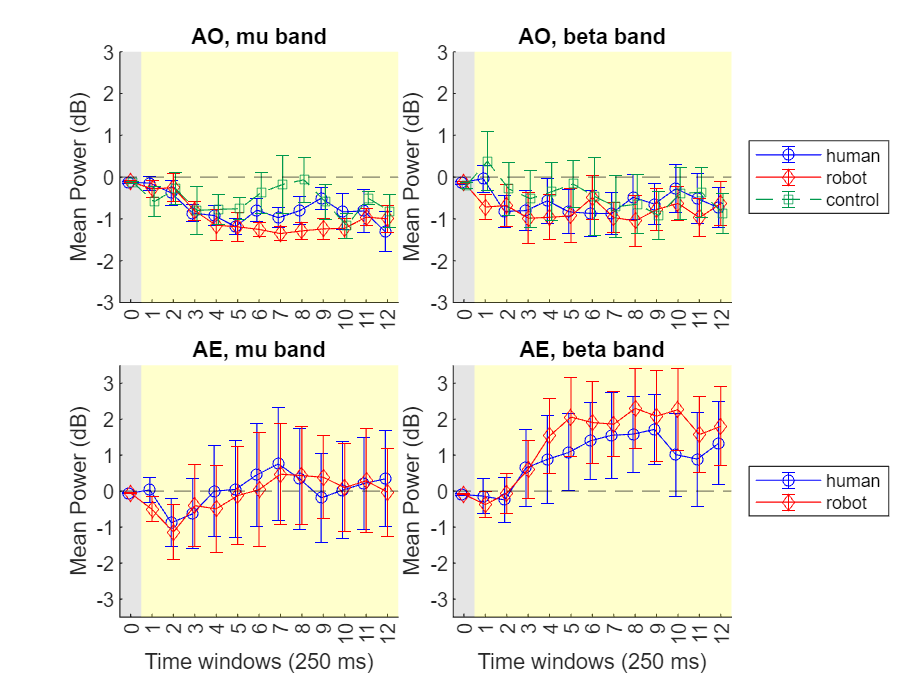

AO_onset_times = 1000;
AE_onset_times = 0;
window_size = 250;
% find the indices of time points lying within consecutive time windows of 250 seconds  
AO_window_idx = extract_window_indices_wbl(AO_times, AO_onset_times, window_size, AO_baseline*1000);
AE_window_idx = extract_window_indices_wbl(AE_times, AE_onset_times, window_size, AE_baseline*1000);

x_shift= [-0.1 0 0.1];


AO_cond_names = ["human", "robot", "control"];
AE_cond_names = ["human", "robot"];

markerColor_new = {"b", "r", [0 0.6 0.3] };
markerCurveStyle_new = ["-", "-", "--" ];
markerSymbol_new = ["o", "diamond", 'square'];

fig = figure; t0 = tiledlayout(2,2, "TileSpacing","tight");
% title(t0, 'Average across all subjects & channels')

exp = 1;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(trials));

    for trial_idx = 1:length(trials)
        nested_cell = cell(length(AO_markerVal_cell), length(AO_window_idx) );
        for cond = 1:length(AO_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AO_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AO_cond_names), length(AO_window_idx));
        for tw = 1:length(AO_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
            nested_cell_new{3, tw} = nested_cell{5,tw};
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AO_window_idx)
            for cond = 1:length(AO_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(trials));    

    x = 0:numel(AO_window_idx)-1;
    for cond = 1:3
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3 3])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)    
    % xlabel('Time windows (250 ms)');
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AO, ' band_names{band} ' band']);
    hold off
end
legend(AO_cond_names, 'Location','eastoutside')


exp = 2;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(trials));

    for trial_idx = 1:length(trials)
        nested_cell = cell(length(AE_markerVal_cell), length(AE_window_idx) );
        for cond = 1:length(AE_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AE_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AE_cond_names), length(AE_window_idx));
        for tw = 1:length(AE_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AE_window_idx)
            for cond = 1:length(AE_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(trials));    

    x = 0:numel(AE_window_idx)-1;
    for cond = 1:length(AE_cond_names)
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3.5 3.5])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)
    xlabel('Time windows (250 ms)'); 
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AE, ' band_names{band} ' band']);
    hold off
end
legend(AE_cond_names, 'Location','eastoutside')
saveas(fig, [filepath 'figures\' 'Temporal ERD - Average across all subjects, channels' '.png']);

5.14.24: During AO, there consistent ERD in both alpha and beta band after about 500-750ms (agree with literature - Duann 2016). 

Comparing with Duann study which show short ERD time course (due to the nature of the stimuli - watch hand clenching),

in this study (n=3), ERD is present till the end of the stimuli and becomes significant different from control condition after 1250 ms

During AO, human and robot condition show no significant difference in alpha and beta band

During 

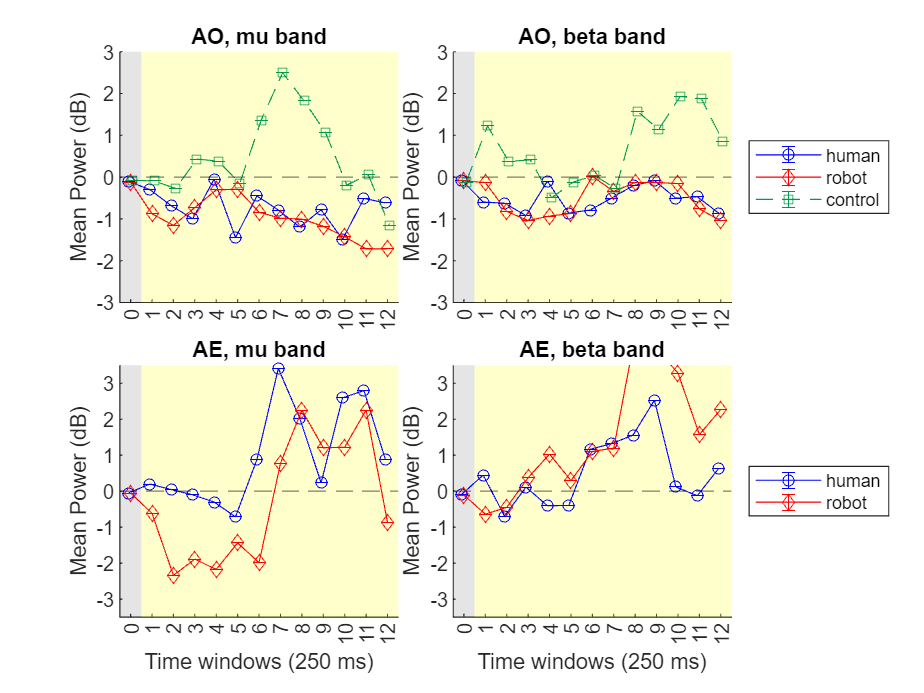

fig = figure; t0 = tiledlayout(2,2, "TileSpacing","tight");
% title(t0, 'Average across all subjects & channels')

exp = 1;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(stroke_group));

    for trial_idx = 1:length(stroke_group)
        nested_cell = cell(length(AO_markerVal_cell), length(AO_window_idx) );
        for cond = 1:length(AO_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AO_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_window_idx{tw}) ;
            end
        end

        % collapsing observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AO_cond_names), length(AO_window_idx));
        for tw = 1:length(AO_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
            nested_cell_new{3, tw} = nested_cell{5,tw};
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AO_window_idx)
            for cond = 1:length(AO_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(stroke_group));    

    x = 0:numel(AO_window_idx)-1;
    for cond = 1:3
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3 3])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)    
    % xlabel('Time windows (250 ms)');
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AO, ' band_names{band} ' band']);
    hold off
end
legend(AO_cond_names, 'Location','eastoutside')


exp = 2;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(stroke_group));

    for trial_idx = 1:length(stroke_group)
        nested_cell = cell(length(AE_markerVal_cell), length(AE_window_idx) );
        for cond = 1:length(AE_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AE_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AE_cond_names), length(AE_window_idx));
        for tw = 1:length(AE_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AE_window_idx)
            for cond = 1:length(AE_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(stroke_group));    

    x = 0:numel(AE_window_idx)-1;
    for cond = 1:length(AE_cond_names)
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3.5 3.5])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)
    xlabel('Time windows (250 ms)'); 
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AE, ' band_names{band} ' band']);
    hold off
end
legend(AE_cond_names, 'Location','eastoutside')
saveas(fig, [filepath 'figures\' 'Temporal ERD - stroke subject, channels' '.png']);

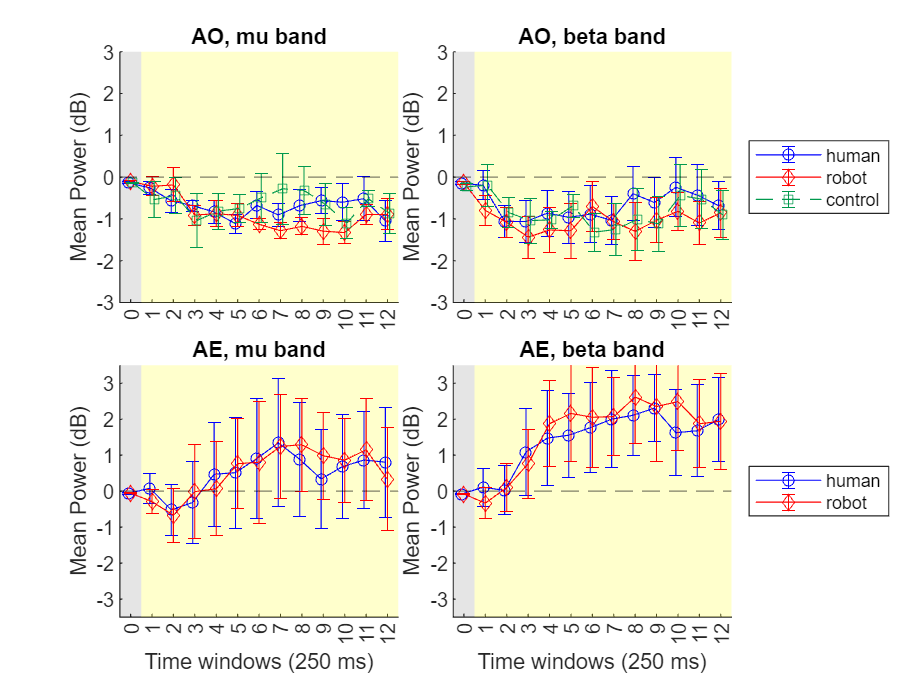

fig = figure; t0 = tiledlayout(2,2, "TileSpacing","tight");
% title(t0, 'Average across all subjects & channels')

exp = 1;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(healthy_group));

    for trial_idx = 1:length(healthy_group)
        nested_cell = cell(length(AO_markerVal_cell), length(AO_window_idx) );
        for cond = 1:length(AO_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AO_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AO_cond_names), length(AO_window_idx));
        for tw = 1:length(AO_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
            nested_cell_new{3, tw} = nested_cell{5,tw};
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AO_window_idx)
            for cond = 1:length(AO_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(healthy_group));    

    x = 0:numel(AO_window_idx)-1;
    for cond = 1:3
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3 3])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)    
    % xlabel('Time windows (250 ms)');
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AO, ' band_names{band} ' band']);
    hold off
end
legend(AO_cond_names, 'Location','eastoutside')


exp = 2;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(healthy_group));

    for trial_idx = 1:length(healthy_group)
        nested_cell = cell(length(AE_markerVal_cell), length(AE_window_idx) );
        for cond = 1:length(AE_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AE_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AE_cond_names), length(AE_window_idx));
        for tw = 1:length(AE_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AE_window_idx)
            for cond = 1:length(AE_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(healthy_group));    

    x = 0:numel(AE_window_idx)-1;
    for cond = 1:length(AE_cond_names)
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3.5 3.5])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)
    xlabel('Time windows (250 ms)'); 
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AE, ' band_names{band} ' band']);
    hold off
end
legend(AE_cond_names, 'Location','eastoutside')
saveas(fig, [filepath 'figures\' 'Temporal ERD - Average across healthy subjects, channels' '.png']);

fig = figure; t0 = tiledlayout(2,2, "TileSpacing","tight");
% title(t0, 'Average across all subjects & channels')

exp = 1;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(healthy_group));

    for trial_idx = 1:length(healthy_group)
        nested_cell = cell(length(AO_markerVal_cell), length(AO_window_idx) );
        for cond = 1:length(AO_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AO_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AO_bands{band}(1) & freqs <= AO_bands{band}(end), AO_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AO_cond_names), length(AO_window_idx));
        for tw = 1:length(AO_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
            nested_cell_new{3, tw} = nested_cell{5,tw};
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AO_window_idx)
            for cond = 1:length(AO_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(healthy_group));    

    x = 0:numel(AO_window_idx)-1;
    for cond = 1:3
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3 3])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)    
    % xlabel('Time windows (250 ms)');
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AO, ' band_names{band} ' band']);
    hold off
end
legend(AO_cond_names, 'Location','eastoutside')


exp = 2;
for band = 1:length(band_names)

    nexttile(t0); hold on
    
    averaged_data_trials = cell(1,length(healthy_group));

    for trial_idx = 1:length(healthy_group)
        nested_cell = cell(length(AE_markerVal_cell), length(AE_window_idx) );
        for cond = 1:length(AE_markerVal_cell)
            % average by channels
            ersp_cond_cell = (ALL_ERSP_trial{trial_idx}{1, exp}{cond}+ ALL_ERSP_trial{trial_idx}{1, exp}{cond})/2;
            for tw = 1:length(AE_window_idx)
                nested_cell{cond, tw} = ersp_cond_cell(freqs >= AE_bands{band}(1) & freqs <= AE_bands{band}(end), AE_window_idx{tw}) ;
            end
        end

        % average by observed hands
        cond = [1,3];
        nested_cell_new = cell(length(AE_cond_names), length(AE_window_idx));
        for tw = 1:length(AE_window_idx)
            for i = 1:2
                nested_cell_new{i,tw} = (nested_cell{cond(i), tw} + nested_cell{cond(i)+1, tw})/2;
            end
        end

        % average across all frequencies within freq band and time (within # determined TWs)
        for tw = 1:length(AE_window_idx)
            for cond = 1:length(AE_cond_names)
                nested_cell_new{cond, tw} = mean(nested_cell_new{cond, tw}, "all");
            end
        end
        averaged_data_trials{trial_idx} = cell2mat(nested_cell_new);
        
    end   
    averaged_data_trials = cat(3, averaged_data_trials{:});

    % Compute mean and standard error of means along the third dimension (subjects)
    combined_mean_data = mean(averaged_data_trials, 3);
    combined_sem_data = std(averaged_data_trials, 0, 3)/sqrt(length(healthy_group));    

    x = 0:numel(AE_window_idx)-1;
    for cond = 1:length(AE_cond_names)
        errorbar(x+x_shift(cond), combined_mean_data(cond,:), combined_sem_data(cond,:), "Marker", markerSymbol_new(cond), ...
            'Color',markerColor_new{cond}, "LineStyle", markerCurveStyle_new(cond),"MarkerSize", markerSize);
    end

    xticks(x);
    xlim([x(1)-.5 x(end)+.5]); ylim([-3.5 3.5])
    xregion(-0.5, 0.5, FaceColor="k", FaceAlpha=0.1); xregion(0.5, x(end)+.5, FaceColor="y", FaceAlpha=0.2)
    xlabel('Time windows (250 ms)'); 
    ylabel('Mean Power (dB)'); yline(0, 'k--', 'Alpha', 0.5)
    title(['AE, ' band_names{band} ' band']);
    hold off
end
legend(AE_cond_names, 'Location','eastoutside')
saveas(fig, [filepath 'figures\' 'Temporal ERD - Average across healthy subjects, channels' '.png']);
